# **MarkerChan demo**

Fs = 1000;
rng('default');
events = double(logical(poissrnd(30/Fs, 1000, 1)));

ind1 = find(events);
codes  = logical(poissrnd(3/10, length(ind1), 1)) ...
    + logical(poissrnd(2/10, length(ind1), 1)) .*2 ...
    + logical(poissrnd(1/10, length(ind1), 1)) .*3 

codes =      2
     2
     3
     0
     3
     0
     0
     1
     1
     3


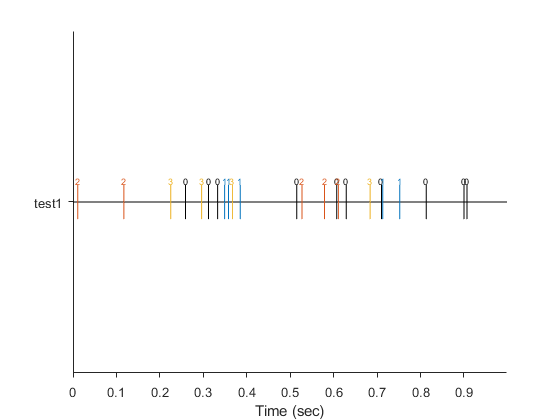


M = MarkerChan(events, 0, Fs, codes, 'test1'); % 370 byte
h = M.plot;

M.testProperties;

  MarkerChan with properties:

                Data: [1000×1 double]
    IsMarkerFilterOn: 0
        MarkerFilter: [256×4 table]
          MarkerName: [256×4 table]
            TextMark: {24×1 cell}
         MarkerCodes: [24×4 table]
                 ISI: [23×1 double]
         InstantRate: [21×1 double]
          TimeStamps: [24×1 double]
          FiringRate: 24.0240
             NSpikes: 24
               Stats: [1×1 struct]
           ChanTitle: 'test1'
            DataUnit: ''
               Start: 0
               SRate: 1000
              Header: [1×1 struct]
                Path: ''
          ChanNumber: 0
           SInterval: 1.0000e-03
              Length: 1000
             MaxTime: 0.9990
            TimeUnit: 'second'

Properties appear to be OK


methods(M)

Methods for class MarkerChan:

MarkerChan                mode                      plotWaveletCoherence      
addEvents                 neurospec_EveEve_sp2_m1   plotWaveletScalogram      
chan2struct               neurospec_WavEve_sp2a_m1  plus                      
chan2ts                   nextSpike                 prevSpike                 
deleteEvents              plot                      resample                  
eq                        plotCV2hist               saveobj                   
extractTime               plotCV2vsISIpair          setMarkerName             
getChanInfo               plotCorr                  std                       
getSpikeInfo              plotISIbefaft             subsasgn                  
getSpikeInfoAll           plotISIhist               sum                       
getstatesAsLogical        plotInstantRate           testProperties            
importEvents              plotMeanFiringRate        time                      
markerfilter         

save() and load()

testCase = MarkerChan_test;
f = matlab.unittest.fixtures.WorkingFolderFixture;
testCase.applyFixture(f);

save M M
S = load('M')

S = struct with fields:
    M: [1×1 MarkerChan]



S.M.testProperties;

  MarkerChan with properties:

                Data: [1000×1 double]
    IsMarkerFilterOn: 0
        MarkerFilter: [256×4 table]
          MarkerName: [256×4 table]
            TextMark: {24×1 cell}
         MarkerCodes: [24×4 table]
                 ISI: [23×1 double]
         InstantRate: [21×1 double]
          TimeStamps: [24×1 double]
          FiringRate: 24.0240
             NSpikes: 24
               Stats: [1×1 struct]
           ChanTitle: 'test1'
            DataUnit: ''
               Start: 0
               SRate: 1000
              Header: [1×1 struct]
                Path: ''
          ChanNumber: 0
           SInterval: 1.0000e-03
              Length: 1000
             MaxTime: 0.9990
            TimeUnit: 'second'

Properties appear to be OK


clear testCase

**Spike2 data**

path = (fileparts(which('MarkerChan.m')));

S_mark = load(fullfile(path, 'BinFreq0MarkAs1.mat')); % S1.demo_LTSmk
S_binned = load(fullfile(path, 'BinFreq17000MarkAs0.mat')); % S2.demo_LTSmk
S_textmark = load(fullfile(path, 'BinFreq0TMarkAs2.mat')); % S3.demo_textmk

%% you need to get start and sRateNew from another binned channel

data = S_binned.demo_LTSmk.values;
start = S_binned.demo_LTSmk.start;
srate = 1/S_binned.demo_LTSmk.interval;
name = S_binned.demo_LTSmk.title;
codes = S_mark.demo_LTSmk.codes;

M1 = MarkerChan(data, start, srate, codes, name);
M1.testProperties;

  MarkerChan with properties:

                Data: [1700000×1 double]
    IsMarkerFilterOn: 0
        MarkerFilter: [256×4 table]
          MarkerName: [256×4 table]
            TextMark: {98×1 cell}
         MarkerCodes: [98×4 table]
                 ISI: [97×1 double]
         InstantRate: [95×1 double]
          TimeStamps: [98×1 double]
          FiringRate: 0.9800
             NSpikes: 98
               Stats: [1×1 struct]
           ChanTitle: 'LTSmk'
            DataUnit: ''
               Start: 0
               SRate: 17000
              Header: [1×1 struct]
                Path: ''
          ChanNumber: 0
           SInterval: 5.8824e-05
              Length: 1700000
             MaxTime: 99.9999
            TimeUnit: 'second'

Properties appear to be OK


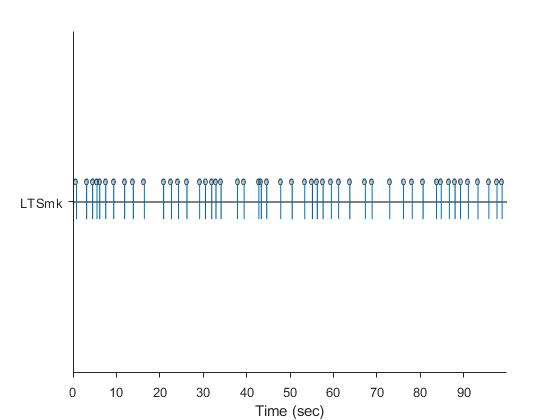

ans = struct with fields:
    fig: [1×1 Figure]
     ax: [1×1 Axes]
     l1: [1×1 Line]
     l2: {2×1 cell}


M1.plot


% Marker channel
M2 = MarkerChan(S_mark.demo_LTSmk, S_binned.demo_LTSmk);
M2.testProperties;

  MarkerChan with properties:

                Data: [1700000×1 double]
    IsMarkerFilterOn: 0
        MarkerFilter: [256×4 table]
          MarkerName: [256×4 table]
            TextMark: {98×1 cell}
         MarkerCodes: [98×4 table]
                 ISI: [97×1 double]
         InstantRate: [95×1 double]
          TimeStamps: [98×1 double]
          FiringRate: 0.9800
             NSpikes: 98
               Stats: [1×1 struct]
           ChanTitle: 'LTSmk'
            DataUnit: ''
               Start: 0
               SRate: 17000
              Header: [1×1 struct]
                Path: ''
          ChanNumber: 0
           SInterval: 5.8824e-05
              Length: 1700000
             MaxTime: 99.9999
            TimeUnit: 'second'

Properties appear to be OK


M2.plot

ans = struct with fields:
    fig: [1×1 Figure]
     ax: [1×1 Axes]
     l1: [1×1 Line]
     l2: {2×1 cell}


copyobj(gca,figure)

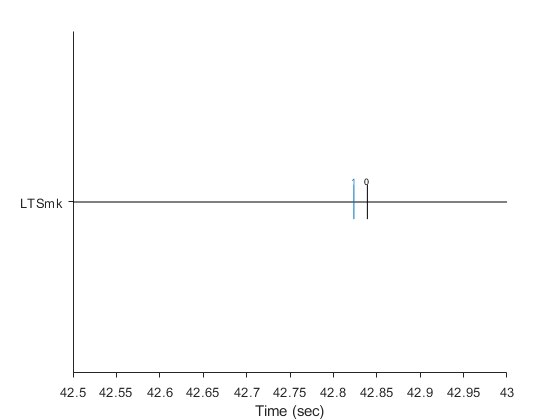

xlim([42.5 43])


% TextMark channel
M3 = MarkerChan(S_textmark.demo_textmk, S_binned.demo_LTSmk);
M3.testProperties;

  MarkerChan with properties:

                Data: [1700000×1 double]
    IsMarkerFilterOn: 0
        MarkerFilter: [256×4 table]
          MarkerName: [256×4 table]
            TextMark: {98×1 cell}
         MarkerCodes: [98×4 table]
                 ISI: [97×1 double]
         InstantRate: [95×1 double]
          TimeStamps: [98×1 double]
          FiringRate: 0.9800
             NSpikes: 98
               Stats: [1×1 struct]
           ChanTitle: 'textmk'
            DataUnit: ''
               Start: 0
               SRate: 17000
              Header: [1×1 struct]
                Path: ''
          ChanNumber: 0
           SInterval: 5.8824e-05
              Length: 1700000
             MaxTime: 99.9999
            TimeUnit: 'second'

Properties appear to be OK


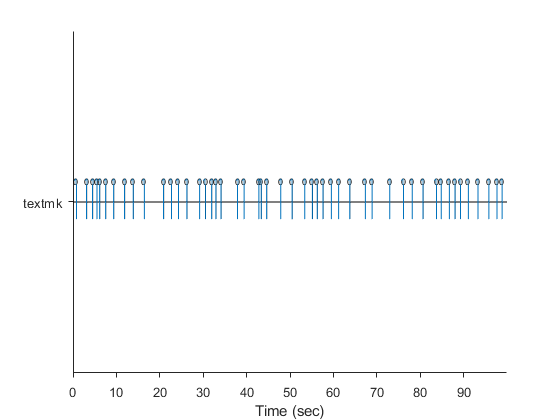

ans = struct with fields:
    fig: [1×1 Figure]
     ax: [1×1 Axes]
     l1: [1×1 Line]
     l2: {2×1 cell}


M3.plot

**Methods**

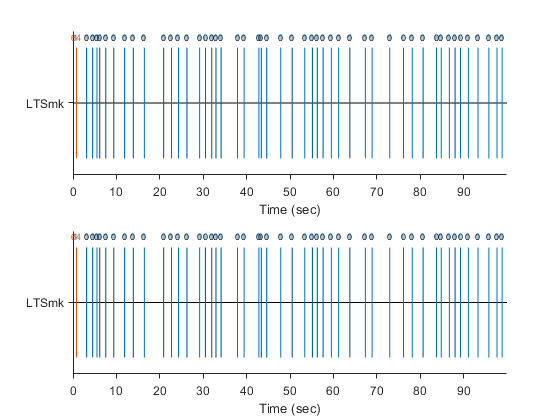

path = (fileparts(which('MarkerChan.m')));

S_mark = load(fullfile(path, 'BinFreq0MarkAs1.mat')); % S1.demo_LTSmk
S_binned = load(fullfile(path, 'BinFreq17000MarkAs0.mat')); % S2.demo_LTSmk

%% you need to get start and sRateNew from another binned channel

% Marker channel
M = MarkerChan(S_mark.demo_LTSmk, S_binned.demo_LTSmk);

%% MarkerCodes subsasgn
M.MarkerCodes(2,:) = [100, 100, 100, 100];

%% getSpikeInfo
spikeinfo = M.getSpikeInfo;
openvar('spikeinfo');
% keyboard

%% resample

M0 = M.resample(1000); %OK 10:39 28/02/2014
figh = figure;
ax1 = subplot(2,1,1);
ax2 = subplot(2,1,2);
M.plot(ax1);
M0.plot(ax2);
linkaxes([ax1 ax2], 'x');

copyobj(figh.Children,figure)

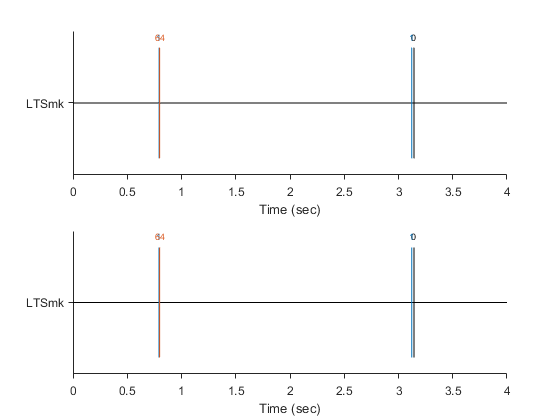

figh2 = gcf;
linkaxes(findobj(figh2,'Type','axes'), 'x');
xlim([0 4])


path = (fileparts(which('MarkerChan.m')));

S_mark = load(fullfile(path, 'BinFreq0MarkAs1.mat')); % S1.demo_LTSmk
S_binned = load(fullfile(path, 'BinFreq17000MarkAs0.mat')); % S2.demo_LTSmk



%% you need to get start and sRateNew from another binned channel

% Marker channel
M = MarkerChan(S_mark.demo_LTSmk, S_binned.demo_LTSmk);

M.Data(1) = 1;
M.Data(1)

ans = 1


M.Data(1:3) % should be [1;0;0]

ans =      1
     0
     0


M.Data(1:3) = [1;1;1];
M.Data(1:3) % should be [1;1;1]

ans =      1
     1
     1



M.MarkerCodes(1:3,1) % should be uint8([0;0;0])

ans = 3×1 table
    code0
    _____

      0  
      0  
      0  


% Addition of spikes pads 0 MarkerCodes accordingly
M.MarkerCodes(1) = 5;
M.MarkerCodes(1,1) % should be uint8(5);

ans = table
    code0
    _____

      5  



M.MarkerCodes(1:2,1) % should be uint8([5,0])

ans = 2×1 table
    code0
    _____

      5  
      0  


M.MarkerCodes(1:2,1) = [10,10]';
M.MarkerCodes(1:2,1) % should be uint8([10,10])

ans = 2×1 table
    code0
    _____

     10  
     10  



M.TextMark{1} % should be ''


ans =

  0×0 empty char array



M.TextMark(1) = {'What the fuck are you doing?'};
M.TextMark{1} % should be 'What the fuck are you doing?'

ans = 'What the fuck are you doing?'


M.TextMark{2} % should be ''


ans =

  0×0 empty char array



M.TextMark(1:2) = {'What the fuck are you doing!?';'Breathing.'};
M.TextMark{1} % should be 'What the fuck are you doing!?'

ans = 'What the fuck are you doing!?'

M.TextMark{2} % should be 'Breathing.'

ans = 'Breathing.'

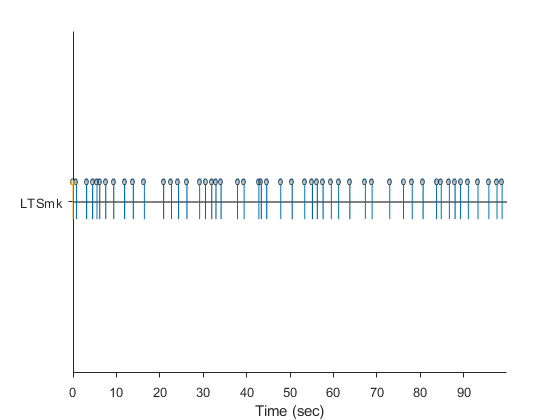

ans = struct with fields:
    fig: [1×1 Figure]
     ax: [1×1 Axes]
     l1: [1×1 Line]
     l2: {11×1 cell}


M.plot


length(M.Data) % should be 1700000

ans = 1700000

M.Data = zeros(20,1);
length(M.Data) % should be 20

ans = 20

M.Data % should be zeros(20,1)

ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


### MarkerFilter

Fs = 1000;
rng('default');
events = double(logical(poissrnd(30/Fs, 1000, 1)));

ind1 = find(events);
codes  = logical(poissrnd(3/10, length(ind1), 1)) ...
    + logical(poissrnd(2/10, length(ind1), 1)) .*2 ...
    + logical(poissrnd(1/10, length(ind1), 1)) .*3 

codes =      2
     2
     3
     0
     3
     0
     0
     1
     1
     3



M = MarkerChan(events, 0, Fs, codes, 'test1'); % 370 byte


M.NSpikes

ans = 24

M.getSpikeInfo

ans = 24×12 table
    id    point    time     ISIbef    ISIaft    InstantRate    code0    code1    code2    code3    MarkerFilter     TextMark 
    __    _____    _____    ______    ______    ___________    _____    _____    _____    _____    ____________    __________

     1      12     0.011    0.011     0.106       90.909         2        0        0        0        Visible       {0×0 char}
     2     118     0.117    0.106     0.108        9.434         2        0        0        0        Visible       {0×0 char}
     3     226     0.225    0.108     0.034       9.2593         3   

ans = struct with fields:
    fig: [1×1 Figure]
     ax: [1×1 Axes]
     l1: [1×1 Line]
     l2: {4×1 cell}


M.plot



M.MarkerFilter(2,1)= false;
M.MarkerFilter{'value3',1} = false;

head(M.MarkerFilter)

ans = 8×4 table
              mask0    mask1    mask2    mask3
              _____    _____    _____    _____

    value0    true     true     true     true 
    value1    false    true     true     true 
    value2    true     true     true     true 
    value3    false    true     true     true 
    value4    true     true     true     true 
    value5    true     true     true     true 
    value6    true     true     true     true 
    value7    true     true     true     true 



M.getSpikeInfo

ans = 15×12 table
    id    point    time     ISIbef    ISIaft    InstantRate    code0    code1    code2    code3    MarkerFilter     TextMark 
    __    _____    _____    ______    ______    ___________    _____    _____    _____    _____    ____________    __________

     1      12     0.011    0.011     0.106       90.909         2        0        0        0        Visible       {0×0 char}
     2     118     0.117    0.106     0.142        9.434         2        0        0        0        Visible       {0×0 char}
     3     260     0.259    0.142     0.053       7.0423         0   

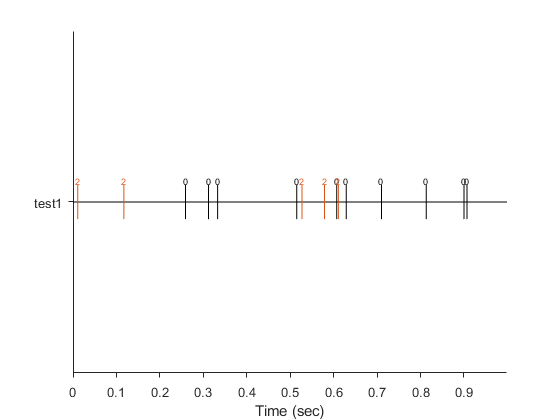

ans = struct with fields:
    fig: [1×1 Figure]
     ax: [1×1 Axes]
     l1: [1×1 Line]
     l2: {3×1 cell}


M.plot


M.getSpikeInfoAll

ans = 24×12 table
    id    point    time     ISIbef    ISIaft    InstantRate    code0    code1    code2    code3    MarkerFilter     TextMark 
    __    _____    _____    ______    ______    ___________    _____    _____    _____    _____    ____________    __________

     1      12     0.012    0.012     0.106       83.333         2        0        0        0        Visible       {0×0 char}
     2     118     0.118    0.106     0.108        9.434         2        0        0        0        Visible       {0×0 char}
     3     226     0.226    0.108     0.034       9.2593         3   



M.MarkerFilter= [];
M.NSpikes

ans = 24

M.getSpikeInfo

ans = 24×12 table
    id    point    time     ISIbef    ISIaft    InstantRate    code0    code1    code2    code3    MarkerFilter     TextMark 
    __    _____    _____    ______    ______    ___________    _____    _____    _____    _____    ____________    __________

     1      12     0.011    0.011     0.106       90.909         2        0        0        0        Visible       {0×0 char}
     2     118     0.117    0.106     0.108        9.434         2        0        0        0        Visible       {0×0 char}
     3     226     0.225    0.108     0.034       9.2593         3   

ans = struct with fields:
    fig: [1×1 Figure]
     ax: [1×1 Axes]
     l1: [1×1 Line]
     l2: {4×1 cell}


M.plot